# Optimal Experiment Design

In this example, we show how TOOFAB can be used to select optimal experiments for parameter estimation, based on a local sensitivity analysis of the DFN model. This example is linked directly to [Weldeghebreal et. al.]. The experiment selection is performed by the function ExperimentSelection, i.e.,

output = ExperimentSelection(equil,options)

The procedure consists of the following steps:

1. A number of candidate experiments is generated. Each candidate is a random current profile, built from discharge and charge pulses of random amplitude and duration, separated by random rest periods. The profile is cut off when the cumulative charge reaches the capacity of the cell.

2. The sensitivity of the terminal voltage of the DFN model to each of the parameters is computed for every candidate experiment, by perturbing the (normalized) parameters around their nominal value and simulating the DFN model. This yields a sensitivity matrix S for each candidate.

3. From the sensitivity matrix, the Fisher information matrix F = S'S is computed, and the candidates are ranked using three optimality criteria: A-optimality (the trace of the inverse of F), D-optimality (the log-determinant of the inverse of F) and E-optimality (the largest eigenvalue of the inverse of F). A lower value indicates a more informative experiment.

4. For each criterion, the best ranked candidate that is not longer than the maximum experiment time is selected as the optimal experiment.

Before we use the script, we first add the main TOOFAB folder to our filepath, such that we can run the example without requiring an independent copy of DFN.m in our current working folder (ExperimentSelection calls the DFN function).

addpath('../..')

## Step 1: Load the equilibrium potential

The experiment selection requires information on the equilibrium potential of the cell. This is provided as a struct, equil, with two fields: EMF (the electromotive force of the cell, as a function of the state of charge) and Cbat (the capacity of the cell in Coulomb). The file equil.mat contains this struct for a 2.85 Ah cell. To use your own cell, replace this file by a file containing a struct equil with the same structure. Note you require the EMF to be present, see the parameter estimation example on how to construct the EMF curve.

load equil.mat

The capacity of the cell, in Ah:

disp(['Cell capacity: ' num2str(equil.Cbat/3600) ' Ah'])

Cell capacity: 2.897 Ah


## Step 2: Specify the options

The options are specified in the struct options. All fields are optional: fields that are not specified take the default value defined at the start of ExperimentSelection.m (150 experiments, a maximum experiment time of 8.75 hours, a cell voltage of 4.18 V, safety limits of -8 A and 8 A, and 200 pulses). The fields are:

options.experiment_amount: the number of candidate experiments that is generated.

options.experiment_time_max: the maximum time of the selected experiments (in hours). Set this to inf if no limit is wanted.

options.cell_voltage: the (initial) voltage of the cell in the simulations (in volts).

options.safety_limit: the safety limits of the battery current (in amps). Always specify from the lower to the upper bound, where a negative current is a discharge.

options.number_of_pulses: the maximum number of pulses in a generated experiment.

options.dfn: (optional) settings of the DFN model used in the simulations, for example options.dfn.T_amb (ambient temperature in K) or options.dfn.set_simp. The defaults are the same as the defaults of parameter_determination.m, such that the experiments are selected for the same model, and the same parameterization (parameter ranges and scaling), as used in the parameter estimation.

options.debug: if set to 1, additional information on the selection (such as the ranking of the candidates) is returned in output.debug.

options.experiment_amount = 15;      % Number of generated experiments
options.experiment_time_max = 9;     % Maximum time of the generated experiments (hours)
options.cell_voltage = equil.EMF(1); % Voltage of the cell (volts) - this will be the starting point of discharge
options.safety_limit = [-8, 8];      % Safety limits of the battery (amps) (always specify from lower to upper bound)
options.number_of_pulses = 50;       % Maximum number of pulses in a generated experiment
options.debug = 0;

Note that the number of candidate experiments is kept low in this example, such that it runs quickly. A larger number of candidates (for example the default of 150) gives a larger chance of finding an informative experiment, at the cost of a longer computation time.

## Step 3: Run the experiment selection

We now run the experiment selection procedure. For every candidate experiment, the DFN model is simulated once with the nominal parameters, and twice for every parameter (with a lower and a higher perturbation). The perturbed simulations are run in parallel with parfor, so the computation time depends on the number of candidates, their length and the number of available parallel workers. Because the candidate experiments are random, the selected experiments will differ every time the script is run.

output = ExperimentSelection(equil,options);

Generating Experiments
1/15
2/15
3/15
4/15
5/15
6/15
7/15
8/15
9/15
10/15
11/15
12/15
13/15
14/15
15/15
Starting Sensitivity Analysis
Experiment: 1/15
Experiment: 2/15
Experiment: 3/15
Experiment: 4/15
Experiment: 5/15
Experiment: 6/15
Experiment: 7/15
Experiment: 8/15
Experiment: 9/15
Experiment: 10/15
Experiment: 11/15
Experiment: 12/15
Experiment: 13/15
Experiment: 14/15
Experiment: 15/15
Starting Experiment Selection
Finished Experiment Selection


The output is saved, such that the selected experiments can be used later without repeating the selection:

save ExperimentSelection.mat output

The output struct contains the following fields:

output.Currents and output.Currents_cut: all the generated experiments, and the experiments cut off at the capacity of the battery, respectively.

output.SensitivityMatrices: a cell array containing the sensitivity matrices of the (cut off) experiments.

output.OptimalExperimentA, output.OptimalExperimentD and output.OptimalExperimentE: the optimal experiments (current profiles in amps, sampled at 1 s) selected using the A-optimality, D-optimality and E-optimality criterion, respectively.

## Step 4: Plot the selected experiments

The selected experiments are current profiles, sampled at 1 s. We plot the optimal experiment for each criterion:

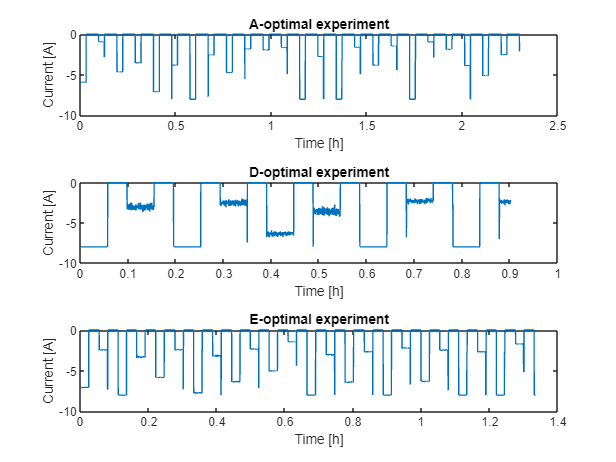

figure;
tiledlayout(3,1);

nexttile
plot((1:length(output.OptimalExperimentA))/3600,output.OptimalExperimentA)
title('A-optimal experiment'); xlabel('Time [h]'); ylabel('Current [A]')

nexttile
plot((1:length(output.OptimalExperimentD))/3600,output.OptimalExperimentD)
title('D-optimal experiment'); xlabel('Time [h]'); ylabel('Current [A]')

nexttile
plot((1:length(output.OptimalExperimentE))/3600,output.OptimalExperimentE)
title('E-optimal experiment'); xlabel('Time [h]'); ylabel('Current [A]')

The duration of the selected experiments (in hours) is:

duration = [length(output.OptimalExperimentA), length(output.OptimalExperimentD), length(output.OptimalExperimentE)]/3600;
disp(table(duration(1),duration(2),duration(3),'VariableNames',{'A_optimal','D_optimal','E_optimal'}))

    A_optimal    D_optimal    E_optimal
    _________    _________    _________

     2.3017       0.90194      1.3353  



## Using the selected experiments

• The selected current profiles can be applied to the cell (for example with a battery cycler), after which the measured data (time, current and voltage) can be used in the parameter estimation method of TOOFAB (see the example ParamEst_DFN_Example).

• Make sure that the safety limits and the cell voltage in the options match the cell and the cycler that you will use for the experiments.

• To inspect the ranking of all candidate experiments, set options.debug = 1. The ranking is then returned in output.debug.